# PubChem_SDQ_LitSearch

Search PubChem for PubMed, Patent, Springer Nature, and Thieme Literature associated with a CID

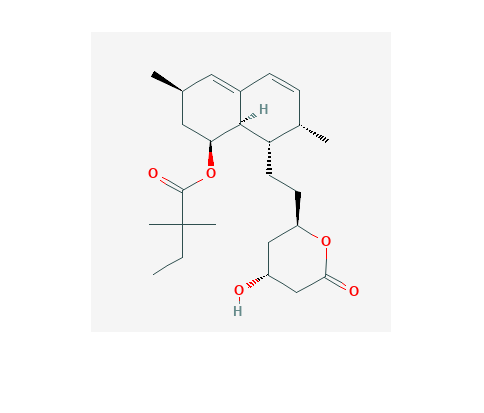

% Vincent F. Scalfani, Serena C. Ralph, Ali Al Alshaikh, and Jason E. Bara 
% The University of Alabama
% Version: 1.0, created with MATLAB R2018a

% N.B. PubChem SDQ query language is not officially supported from PubChem
% Results/syntax may change

% Define PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/cid/';

% Retrieve and display PNG Image of Simvastatin; CID = 54454
CID = '54454';
CID_url = [api CID '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map);

## Explore Total Literature Counts

% Retrieve associated literature reference metadata

% Define PubChem SDQ with JSON output
sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';

% Retrieve total count of associated Simvastatin; CID = 54454 literature references
litCountQ_url = [sdq '{"hide":"*","collection":"*","where":{"ands":{"cid":"54454"}}}'];

% set options to a 30 second timeout and json output
options = weboptions('Timeout', 60, 'ContentType','json');
litCountQ = webread(litCountQ_url, options);

% Display total literature counts of pubmed, patent, springer nature, and Thieme collections
litCountQ_pubmed = litCountQ.SDQOutputSet(6).totalCount;
litCountQ_patent = litCountQ.SDQOutputSet(4).totalCount;
litCountQ_springernature = litCountQ.SDQOutputSet(13).totalCount;
litCountQ_thieme = litCountQ.SDQOutputSet(12).totalCount;

fprintf(['litCountQ_pubmed = %d \nlitCountQ_patent = %d \nlitCountQ_springernature = %d' ...
    '\nlitCountQ_thieme = %d\n'] ,...
    litCountQ_pubmed, litCountQ_patent, litCountQ_springernature, litCountQ_thieme)

litCountQ_pubmed = 9888 
litCountQ_patent = 24610 
litCountQ_springernature = 40011
litCountQ_thieme = 2


## Explore Structure of the Literature Data

% Retrieve 1 associated literature reference from each collection to look at JSON field data

% pubmed
litQpubmed1_url = [sdq '{"select":"*","collection":"pubmed","where":{"ands":{"cid":"54454"}},' ...
    '"start":1,"limit":1}'];
litQpubmed1 = webread(litQpubmed1_url, options);

% patent
litQpatent1_url = [sdq '{"select":"*","collection":"patent","where":{"ands":{"cid":"54454"}},' ...
    '"start":1,"limit":1}'];
litQpatent1 = webread(litQpatent1_url, options);

% springernature
litQspringernature1_url = [sdq '{"select":"*","collection":"springernature","where":{"ands":{"cid":"54454"}},' ...
    '"start":1,"limit":1}'];
litQspringernature1 = webread(litQspringernature1_url, options);

% thieme
litQthieme1_url = [sdq '{"select":"*","collection":"thiemechemistry","where":{"ands":{"cid":"54454"}},' ...
    '"start":1,"limit":1}'];
litQthieme1 = webread(litQthieme1_url, options);

## Search PubMed Collection

% Search pubchem pubmed collection for 
% refs containing meshheadings "simvastatin" and meshsubheadings "chemical synthesis"
% (associated with CID 54454)

litQpubmedF = [sdq '{"select":"*","collection":"pubmed","where":{"ands":{"cid":"54454",' ...
    '"meshheadings":"simvastatin", "meshsubheadings":"chemical synthesis"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQpubmedF = webread(litQpubmedF, options);

% Display results: pmid, articletitle, articlejourname, articleauth, pubmed link

for k = 1:length(litQpubmedF.SDQOutputSet.rows)
    pmid = litQpubmedF.SDQOutputSet.rows{k,1}.pmid
    articletitle = litQpubmedF.SDQOutputSet.rows{k,1}.articletitle
    articleauth = litQpubmedF.SDQOutputSet.rows{k,1}.articleauth
    articlejourname = litQpubmedF.SDQOutputSet.rows{k,1}.articlejourname
    citation = litQpubmedF.SDQOutputSet.rows{k,1}.citation
    
    pubmed_root = 'https://www.ncbi.nlm.nih.gov/pubmed/?term=';
    pmid = num2str(pmid);
    pubmed_link = [pubmed_root pmid];
    fprintf('<a href = " %s ">%s</a>\n', pubmed_link, pubmed_link)
    disp(' ')
end

pmid = 17277201

articletitle = 'Efficient synthesis of simvastatin by use of whole-cell biocatalysis.'

articleauth = 'Xinkai Xie, Yi Tang'

articlejourname = 'Applied and environmental microbiology'

citation = '2007 Apr;73(7):2054-60'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=17277201 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=17277201</a>


pmid = 9162756

articletitle = 'Ro 48-8.071, a new 2,3-oxidosqualene:lanosterol cyclase inhibitor lowering plasma cholesterol in hamsters, squirrel monkeys, and minipigs: comparison to simvastatin.'

articleauth = 'O H Morand, J D Aebi, H Dehmlow, Y H Ji, N Gains, H Lengsfeld, J Himber'

articlejourname = 'Journal of lipid research'

citation = '1997 Feb;38(2):373-90'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=9162756 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=9162756</a>


pmid = 26863535

articletitle = 'Simvastatin Sodium Salt and Fluvastatin Interact with Human Gap Junction Gamma-3 Protein.'

articleauth = 'Andrew Marsh, Katherine Casey-Green, Fay Probert, David Withall, Daniel A Mitchell, Suzanne J Dilly, Sean James, Wade Dimitri, Sweta R Ladwa, Paul C Taylor, Donald R J Singer'

articlejourname = 'PloS one'

citation = '2016 Jan;11(2):e0148266'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=26863535 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=26863535</a>


pmid = 17697761

articletitle = 'Structural elucidation of an unknown Simvastatin by-product in industrial synthesis starting from Lovastatin.'

articleauth = 'Vittorio Bertacche, Alberto Milanese, Donatella Nava, Elena Pini, Riccardo Stradi'

articlejourname = 'Journal of pharmaceutical and biomedical analysis'

citation = '2007 Nov;45(4):642-7'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=17697761 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=17697761</a>


pmid = 24143094

articletitle = 'Local delivery of controlled-release simvastatin/PLGA/HAp microspheres enhances bone repair.'

articleauth = 'I-Chun Tai, Yin-Chih Fu, Chih-Kuang Wang, Je-Ken Chang, Mei-Ling Ho'

articlejourname = 'International journal of nanomedicine'

citation = '2013 Jan;8(?):3895-904'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=24143094 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=24143094</a>


pmid = 25115530

articletitle = 'A novel anabolic agent: a simvastatin analogue without HMG-CoA reductase inhibitory activity.'

articleauth = 'Kuang-Chan Hsieh, Chai-Lin Kao, Chien-Wei Feng, Zhi-Hong Wen, Hsin-Fang Chang, Shu-Chun Chuang, Gwo-Jaw Wang, Mei-Ling Ho, Shou-Mei Wu, Je-Ken Chang, Hui-Ting Chen'

articlejourname = 'Organic letters'

citation = '2014 Sep;16(17):4376-9'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=25115530 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=25115530</a>


pmid = 26353590

articletitle = 'A Titanium Surface-Modified with Nano-Sized Hydroxyapatite and Simvastatin Enhances Bone Formation and Osseintegration.'

articleauth = 'Yong-Dae Kwon, Dae Hyeok Yang, Deok-Won Lee'

articlejourname = 'Journal of biomedical nanotechnology'

citation = '2015 Jun;11(6):1007-15'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=26353590 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=26353590</a>


pmid = 1433193

articletitle = '3-Hydroxy-3-methylglutaryl-coenzyme A reductase inhibitors. 9. The synthesis and biological evaluation of novel simvastatin analogs.'

articleauth = 'G D Hartman, W Halczenko, M E Duggan, J S Imagire, R L Smith, S M Pitzenberger, S L Fitzpatrick, A W Alberts, R Bostedor, Y S Chao'

articlejourname = 'Journal of medicinal chemistry'

citation = '1992 Oct;35(21):3813-21'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=1433193 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=1433193</a>


pmid = 24160569

articletitle = 'Preparation and characterization of Simvastatin solid dispersion using skimmed milk.'

articleauth = 'P A Sonar, A L Behera, S K Banerjee, D D Gaikwad, S L Harer'

articlejourname = 'Drug development and industrial pharmacy'

citation = '2015 Jan;41(1):22-7'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=24160569 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=24160569</a>


pmid = 28397414

articletitle = 'Development of Bilayer Tablets with Modified Release of Selected Incompatible Drugs.'

articleauth = 'Neha Dhiman, Rajendra Awasthi, Shammy Jindal, Smriti Khatri, Kamal Dua'

articlejourname = 'Polimery w medycynie'

citation = '2016 Jan;46(1):5-15'

<a href = " https://www.ncbi.nlm.nih.gov/pubmed/?term=28397414 ">https://www.ncbi.nlm.nih.gov/pubmed/?term=28397414</a>


## Search Patent Collection

% Search pubchem patent collection for patents with "simvastatin" and "preparation" in the title
% (associated with CID 54454)
litQpatentF = [sdq '{"select":"*","collection":"patent","where":{"ands":{"cid":"54454",' ...
    '"patenttitle":"simvastatin", "patenttitle":"preparation"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQpatentF = webread(litQpatentF, options);

% Display results: patentID, patenttitle, patentinventor, and patenturl
for k = 1:length(litQpatentF.SDQOutputSet.rows)
    patentID = litQpatentF.SDQOutputSet.rows{k,1}.patentid
    patenttitle = litQpatentF.SDQOutputSet.rows{k,1}.patenttitle
    patentdate = litQpatentF.SDQOutputSet.rows{k,1}.patentdate
    patentinventor = litQpatentF.SDQOutputSet.rows{k,1}.patentinventor
    patenturl = litQpatentF.SDQOutputSet.rows{k,1}.patenturl;
    fprintf('<a href = " %s ">%s</a>', patenturl, patenturl)
    disp(' ')
end

patentID = 'US2010240116'

patenttitle = 'LOVASTATIN ESTERASE ENZYME IMMOBILIZED ON SOLID SUPPORT, PROCESS FOR ENZYME IMMOBILIZATION, USE OF IMMOBILIZED ENZYME, BIOCATALYTIC FLOW REACTOR AND PROCESS FOR PREPARATION AND/OR PURIFICATION OF SIMVASTATIN'

patentdate = '20100923'

patentinventor = 'KOSZELEWSKI DOMINIK [PL],KUREK WALDEMAR [PL],OSTASZEWSKI RYSZARD [PL],PATRALSKA DOROTA [PL]'

<a href = " http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20100240116.PN.&OS=PN/20100240116&RS=PN/20100240116 ">http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20100240116.PN.&OS=PN/20100240116&RS=PN/20100240116</a>

patentID = 'US6384238'

patenttitle = 'Process for the preparation of simvastatin and analogs thereof'

patentdate = '20020507'

patentinventor = 'ZLICAR MARCO [SI]'

<a href = " http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6384238.PN.&OS=PN/6384238&RS=PN/6384238 ">http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6384238.PN.&OS=PN/6384238&RS=PN/6384238</a>

patentID = 'WO0032585'

patenttitle = 'PROCESS FOR THE PREPARATION OF SIMVASTATIN AND ANALOGS THEREOF'

patentdate = '20000608'

patentinventor = 'ZLICAR MARCO [SI]'

<a href = " http://patentscope.wipo.int/search/en/detail.jsf?docId=WO2000032585 ">http://patentscope.wipo.int/search/en/detail.jsf?docId=WO2000032585</a>

patentID = 'US2005239885'

patenttitle = 'Processes for the preparation of simvastatin'

patentdate = '20051027'

patentinventor = 'RAO KODALI E [IN],JOSHI NARENDRA S [IN],BHIRUD SHEKHAR B [IN]'

<a href = " http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20050239885.PN.&OS=PN/20050239885&RS=PN/20050239885 ">http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20050239885.PN.&OS=PN/20050239885&RS=PN/20050239885</a>

patentID = 'US6984399'

patenttitle = 'Solid pharmaceutical formulation containing lovastatin and simvastatin respectively, and its preparation'

patentdate = '20060110'

patentinventor = 'Aleksander Resman,Mateja Salobir,Zdenka Jerala,Zlatko Pflaum'

<a href = " http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6984399.PN.&OS=PN/6984399&RS=PN/6984399 ">http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6984399.PN.&OS=PN/6984399&RS=PN/6984399</a>

patentID = 'US6696086'

patenttitle = 'Solid pharmaceutical formulation containing lovastatin and simvastatin, respectively, and its preparation'

patentdate = '20040224'

patentinventor = 'Aleksander Resman,Mateja Salobir,Zdenka Jerala,Zlatko Pflaum'

<a href = " http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6696086.PN.&OS=PN/6696086&RS=PN/6696086 ">http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=6696086.PN.&OS=PN/6696086&RS=PN/6696086</a>

patentID = 'US2009005425'

patenttitle = 'Complex Formulation Comprising Amlodipine Camsylate And Simvastatin and Method For Preparation Thereof'

patentdate = '20090101'

patentinventor = 'CHI MOON HYUK [KR],KIM YONG II [KR],WOO JONG SOO [KR],YI HONG GI [KR]'

<a href = " http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20090005425.PN.&OS=PN/20090005425&RS=PN/20090005425 ">http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20090005425.PN.&OS=PN/20090005425&RS=PN/20090005425</a>

patentID = 'EP0511867'

patenttitle = 'Process for the preparation of simvastatin'

patentdate = '19960821'

patentinventor = 'DABORA REBECCA L [US],TEWALT GREGORY L [US]'

<a href = " http://worldwide.espacenet.com/publicationDetails/biblio?CC=EP&FT=D&NR=0511867B1&KC=B1 ">http://worldwide.espacenet.com/publicationDetails/biblio?CC=EP&FT=D&NR=0511867B1&KC=B1</a>

patentID = 'US2005004215'

patenttitle = 'Amorphous simvastatin calcium and methods for the preparation thereof'

patentdate = '20050106'

patentinventor = 'BODI ISTVAN [HU],FEHER ERIKA [HU],KORODI FERENC [HU],KOVACSNE-MEZEI ADRIENNE [HU],SZABO CSABA [HU]'

<a href = " http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20050004215.PN.&OS=PN/20050004215&RS=PN/20050004215 ">http://appft.uspto.gov/netacgi/nph-Parser?p=1&u=%2Fnetahtml%2FPTO%2Fsearch-adv.html&r=1&f=G&l=50&d=PG01&s1=20050004215.PN.&OS=PN/20050004215&RS=PN/20050004215</a>

patentID = 'US7528265'

patenttitle = 'Process for the preparation of simvastatin'

patentdate = '20090505'

patentinventor = 'CHANG YOUNGKIL [KR],HA TAEHEE [KR],LEE GWANSUN [KR],LEE HOECHUL [KR],LEE JAEHEON [KR],PARK CHULHYUN [KR]'

<a href = " http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=7528265.PN.&OS=PN/7528265&RS=PN/7528265 ">http://patft.uspto.gov/netacgi/nph-Parser?d=PALL&p=1&u=%2Fnetahtml%2FPTO%2Fsrchnum.htm&r=1&f=G&l=50&s1=7528265.PN.&OS=PN/7528265&RS=PN/7528265</a>

## Search Springer Nature

% Search springer nature collection for "simvastatin" in the title and publication year 2019
% (associated with CID 54454)
litQspringernatureF = [sdq '{"select":"*","collection":"springernature","where":{"ands":{"cid":"54454",' ...
    '"articletitle":"simvastatin", "articlepubdate":"2019"}},"start":1,"limit":10}'];
options = weboptions('Timeout', 60, 'ContentType','json');
litQspringernatureF = webread(litQspringernatureF, options);

% Display results
for k = 1:length(litQspringernatureF.SDQOutputSet.rows)
    extID = litQspringernatureF.SDQOutputSet.rows{k,1}.extid
    articletitle = litQspringernatureF.SDQOutputSet.rows{k,1}.articletitle
    articlejournalname = litQspringernatureF.SDQOutputSet.rows{k,1}.articlejourname
    articlepubdate = litQspringernatureF.SDQOutputSet.rows{k,1}.articlepubdate
    articleurl = litQspringernatureF.SDQOutputSet.rows{k,1}.url;
    fprintf('<a href = " %s ">%s</a>', articleurl, articleurl)
    disp(' ')
end

extID = '30051972-96267025'

articletitle = 'PAI-1 inhibition by simvastatin as a positive adjuvant in cell therapy'

articlejournalname = 'Molecular Biology Reports'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s11033-018-4562-4 ">https://doi.org/10.1007/s11033-018-4562-4</a>

extID = '30051972-96267025'

articletitle = 'Simvastatin'

articlejournalname = 'Reactions Weekly'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s40278-019-56569-z ">https://doi.org/10.1007/s40278-019-56569-z</a>

extID = '30051972-96295130'

articletitle = 'PAI-1 inhibition by simvastatin as a positive adjuvant in cell therapy'

articlejournalname = 'Molecular Biology Reports'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s11033-018-4562-4 ">https://doi.org/10.1007/s11033-018-4562-4</a>

extID = '30051972-96267025'

articletitle = 'Rosuvastatin/simvastatin'

articlejournalname = 'Reactions Weekly'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s40278-019-56856-7 ">https://doi.org/10.1007/s40278-019-56856-7</a>

extID = '30051972-96267025'

articletitle = 'Simvastatin'

articlejournalname = 'Reactions Weekly'

articlepubdate = '2019'

<a href = " https://doi.org/10.1007/s40278-019-56859-7 ">https://doi.org/10.1007/s40278-019-56859-7</a>

extID = '30051972-96267025'

articletitle = 'High cholesterol triggers white matter alterations and cognitive deficits in a mouse model of cerebrovascular disease: benefits of simvastatin'

articlejournalname = 'Cell Death & Disease'

articlepubdate = '2019'

<a href = " https://doi.org/10.1038/s41419-018-1199-0 ">https://doi.org/10.1038/s41419-018-1199-0</a>

extID = '30051972-96267025'

articletitle = 'The Evaluation of Vitiligous lesions Repigmentation after the Administration of Atorvastatin calcium salt and Simvastatin-acid sodium salt in patients with active vitiligo (EVRAAS), a pilot study: study protocol for a randomized controlled trial'

articlejournalname = 'Trials'

articlepubdate = '2019'

<a href = " https://doi.org/10.1186/s13063-018-3168-4 ">https://doi.org/10.1186/s13063-018-3168-4</a>

extID = '30051972-96295130'

articletitle = 'High cholesterol triggers white matter alterations and cognitive deficits in a mouse model of cerebrovascular disease: benefits of simvastatin'

articlejournalname = 'Cell Death & Disease'

articlepubdate = '2019'

<a href = " https://doi.org/10.1038/s41419-018-1199-0 ">https://doi.org/10.1038/s41419-018-1199-0</a>

extID = '30051972-96295130'

articletitle = 'The Evaluation of Vitiligous lesions Repigmentation after the Administration of Atorvastatin calcium salt and Simvastatin-acid sodium salt in patients with active vitiligo (EVRAAS), a pilot study: study protocol for a randomized controlled trial'

articlejournalname = 'Trials'

articlepubdate = '2019'

<a href = " https://doi.org/10.1186/s13063-018-3168-4 ">https://doi.org/10.1186/s13063-018-3168-4</a>

extID = '30051972-96267025'

articletitle = 'Simvastatin improves olanzapine-induced dyslipidemia in rats through inhibiting hepatic mTOR signaling pathway'

articlejournalname = 'Acta Pharmacologica Sinica'

articlepubdate = '2019'

<a href = " https://doi.org/10.1038/s41401-019-0212-1 ">https://doi.org/10.1038/s41401-019-0212-1</a>

## Retrieve Thieme Chemistry References

% Retrieve all Thieme Chemistry References (only 2 from above lit count)
% (associated with CID 54454)
litQthiemeF = [sdq '{"select":"*","collection":"thiemechemistry","where":{"ands":{"cid":"54454"}},' ...
    '"start":1,"limit":10}'];

options = weboptions('Timeout', 60, 'ContentType','json');
litQthiemeF = webread(litQthiemeF, options);

% Display results
for k = 1:length(litQthiemeF.SDQOutputSet.rows)
    extID = litQthiemeF.SDQOutputSet.rows{k,1}.extid
    articletitle = litQthiemeF.SDQOutputSet.rows{k,1}.articletitle
    articlejournalname = litQthiemeF.SDQOutputSet.rows{k,1}.articlejourname
    articlepubdate = litQthiemeF.SDQOutputSet.rows{k,1}.articlepubdate
    articleurl = litQthiemeF.SDQOutputSet.rows{k,1}.url;
    fprintf('<a href = " %s ">%s</a>', articleurl, articleurl)
    disp(' ')
end

extID = '30051972-96267025'

articletitle = 'Stereoselective Synthesis of a Mevinic Acid Analogue¹'

articlejournalname = 'Synthesis'

articlepubdate = '2007'

<a href = " https://doi.org/10.1055/s-2007-965904 ">https://doi.org/10.1055/s-2007-965904</a>

extID = '30051972-96295130'

articletitle = 'Simvastatin'

articlejournalname = 'Pharmaceutical Substances'

articlepubdate = '2003'

<a href = " https://pharmaceutical-substances.thieme.com/ps/search-results?docUri=KD-19-0030 ">https://pharmaceutical-substances.thieme.com/ps/search-results?docUri=KD-19-0030</a>